clear
load data2.mat
n=length(data.CzasLokalnyUTC0000);

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
all=length(X)

all = 516457

day=24*60*60*fs

day = 17280

t=T*(1:all);
X=X';
X=X(:,1:all);
size(X)

ans =            8      516457


X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

% figure
locs=compressorCycles(X(2,:));
locs=locs(2:end);
x = FeatureExtract(X_filtered(3,:),locs);
% plot((X_filtered(3,:)));hold on
% plot(locs,(X_filtered(3,locs)),'o');hold off
% title('Detection of peaks on Sonda temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
fridge_air_temp_p2p=x(1,:)-x(2,:);

indexContainer=cell(1);
indexContainer{1}=[];
set=1;
% figure
% hold on
TF = isoutlier(fridge_air_temp_p2p);

for i=2:length(x)
    
    if (TF(i)==0)
        % plot(locs(i-1):locs(i),(X_filtered(3,locs(i-1):locs(i))),"Color",'blue');
        % plot(locs(i),(X_filtered(3,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
% hold off
% title('Detection of peaks on evaporator temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*fs*60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

load TrainingLargeDatasets.mat

% for i = 1:length(usableDataIndex)
% % for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y{i},params{i}]=GATrain(X(2,usableDataIndex{i}), X_filtered(1,usableDataIndex{i}),...
%         t_sim, X_filtered(3,usableDataIndex{i}(1)), X_filtered(3,usableDataIndex{i}));
% end

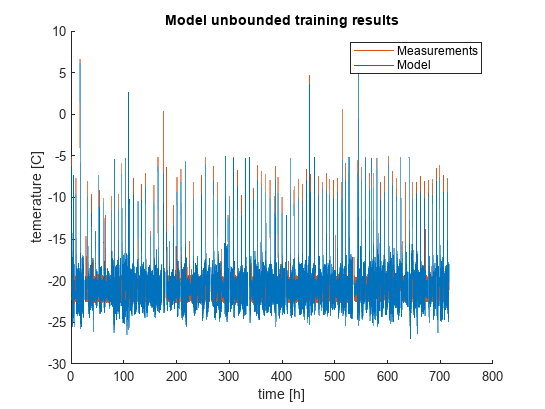

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(3,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

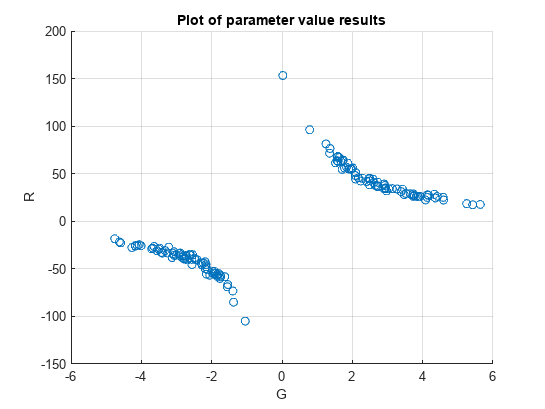

for i = 1:length(params)
resu(i,:)=params{i};
end

figure
plot3(resu(:,1),resu(:,2),resu(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')
% view(0,0)
view(0,90)